% IMU Data of 15 Minutes and Analysis:

s = rosbag("Lab3Short.bag");
imu = select(s, "Topic", "imu/imu_data");
mag = select(s, "Topic", "imu/magnetic_data");
imu_msgs = readMessages(imu,"DataFormat","struct");
mag_msgs = readMessages(mag,"DataFormat","struct");
% imu_msgs{1}
% mag_msgs{1}

imu_seq = cellfun(@(m) double(m.Header.Seq),imu_msgs);
imu_qx = cellfun(@(m) double(m.Orientation.X),imu_msgs);
imu_qy = cellfun(@(m) double(m.Orientation.Y),imu_msgs);
imu_qz = cellfun(@(m) double(m.Orientation.Z),imu_msgs);
imu_qw = cellfun(@(m) double(m.Orientation.W),imu_msgs);
imu_gx = cellfun(@(m) double(m.AngularVelocity.X),imu_msgs);
imu_gy = cellfun(@(m) double(m.AngularVelocity.Y),imu_msgs);
imu_gz = cellfun(@(m) double(m.AngularVelocity.Z),imu_msgs);
imu_ax = cellfun(@(m) double(m.LinearAcceleration.X),imu_msgs);
imu_ay = cellfun(@(m) double(m.LinearAcceleration.Y),imu_msgs);
imu_az = cellfun(@(m) double(m.LinearAcceleration.Z),imu_msgs);

mag_seq = cellfun(@(m) double(m.Header.Seq),mag_msgs);
mag_x = cellfun(@(m) double(m.MagneticField_.X),mag_msgs);
mag_y = cellfun(@(m) double(m.MagneticField_.Y),mag_msgs);
mag_z = cellfun(@(m) double(m.MagneticField_.Z),mag_msgs);

mean_imu_ax = mean(imu_ax)

mean_imu_ax = 1.6475

mean_imu_ay = mean(imu_ay)

mean_imu_ay = 2.4146

mean_imu_az = mean(imu_az)

mean_imu_az = -9.3663

std_imu_ax = std(imu_ax)

std_imu_ax = 0.0125

std_imu_ay = std(imu_ay)

std_imu_ay = 0.0131

std_imu_az = std(imu_az)

std_imu_az = 0.0203


mean_imu_gx = mean(imu_gx)

mean_imu_gx = 9.1167e-05

mean_imu_gy = mean(imu_gy)

mean_imu_gy = 6.3811e-05

mean_imu_gz = mean(imu_gz)

mean_imu_gz = 1.4938e-04

std_imu_gx = std(imu_gx)

std_imu_gx = 6.1624e-04

std_imu_gy = std(imu_gy)

std_imu_gy = 6.6552e-04

std_imu_gz = std(imu_gz)

std_imu_gz = 7.7699e-04


mean_mag_x = mean(mag_x)

mean_mag_x = -0.2909

mean_mag_y = mean(mag_y)

mean_mag_y = -0.1253

mean_mag_z = mean(mag_z)

mean_mag_z = 0.2014

std_mag_x = std(mag_x)

std_mag_x = 7.4901e-04

std_mag_y = std(mag_y)

std_mag_y = 0.0011

std_mag_z = std(mag_z)

std_mag_z = 0.0010

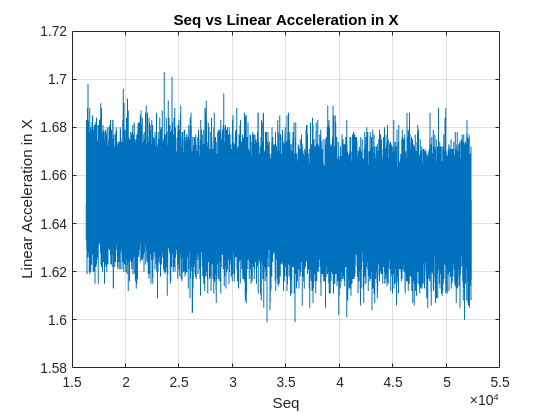


figure(1)
plot(imu_seq, imu_ax);
title("Seq vs Linear Acceleration in X");
xlabel("Seq");
ylabel("Linear Acceleration in X");
grid on

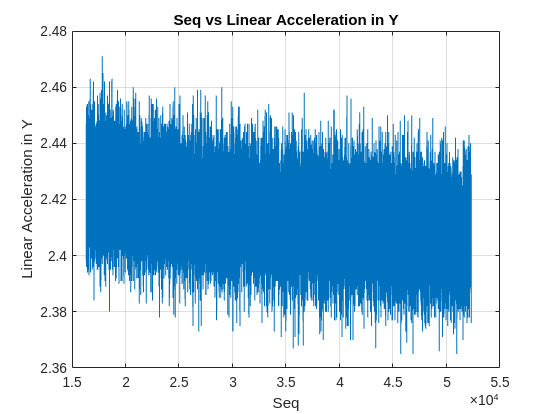


figure(2)
plot(imu_seq, imu_ay);
title("Seq vs Linear Acceleration in Y");
xlabel("Seq");
ylabel("Linear Acceleration in Y");
grid on

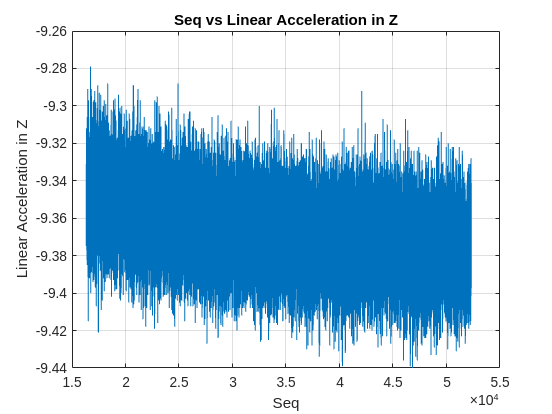


figure(3)
plot(imu_seq, imu_az);
title("Seq vs Linear Acceleration in Z");
xlabel("Seq");
ylabel("Linear Acceleration in Z");
grid on

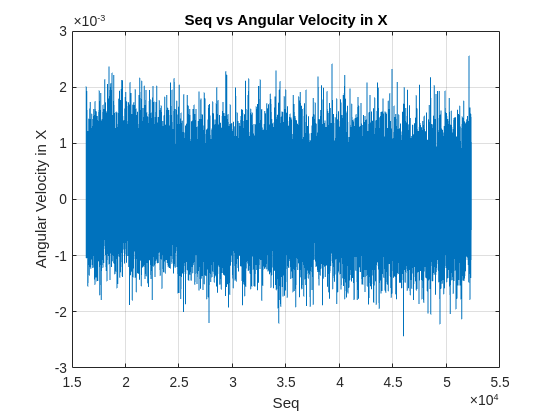


figure(4)
plot(imu_seq, imu_gx);
title("Seq vs Angular Velocity in X");
xlabel("Seq");
ylabel("Angular Velocity in X");
grid on

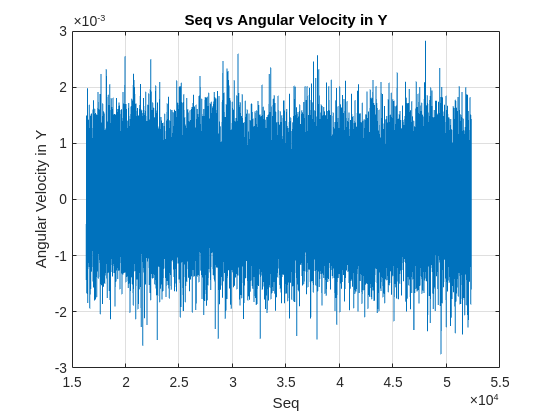


figure(5)
plot(imu_seq, imu_gy);
title("Seq vs Angular Velocity in Y");
xlabel("Seq");
ylabel("Angular Velocity in Y");
grid on

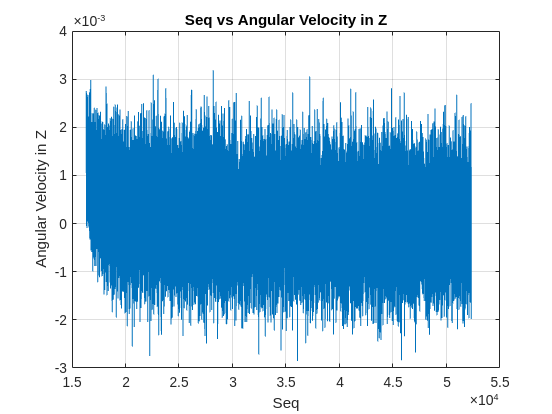


figure(6)
plot(imu_seq, imu_gz);
title("Seq vs Angular Velocity in Z");
xlabel("Seq");
ylabel("Angular Velocity in Z");
grid on

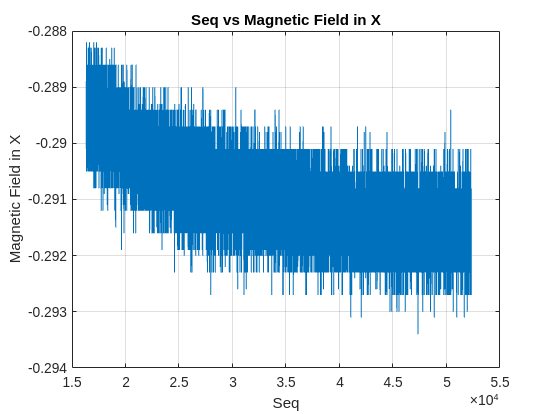


figure(7)
plot(mag_seq, mag_x);
title("Seq vs Magnetic Field in X");
xlabel("Seq");
ylabel("Magnetic Field in X");
grid on

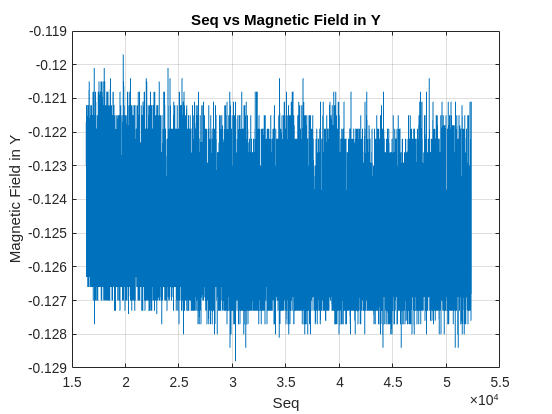


figure(8)
plot(mag_seq, mag_y);
title("Seq vs Magnetic Field in Y");
xlabel("Seq");
ylabel("Magnetic Field in Y");
grid on

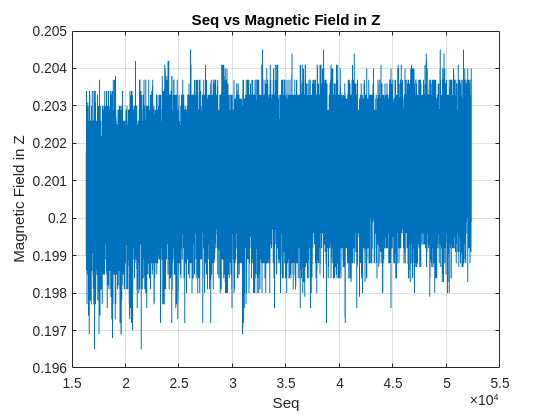


figure(9)
plot(mag_seq, mag_z);
title("Seq vs Magnetic Field in Z");
xlabel("Seq");
ylabel("Magnetic Field in Z");
grid on

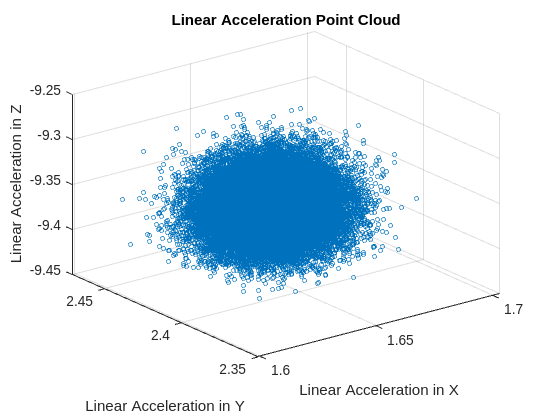


figure(10)
plot3(imu_ax, imu_ay, imu_az, "o", "MarkerSize", 3);
title("Linear Acceleration Point Cloud");
xlabel("Linear Acceleration in X");
ylabel("Linear Acceleration in Y");
zlabel("Linear Acceleration in Z");
grid on

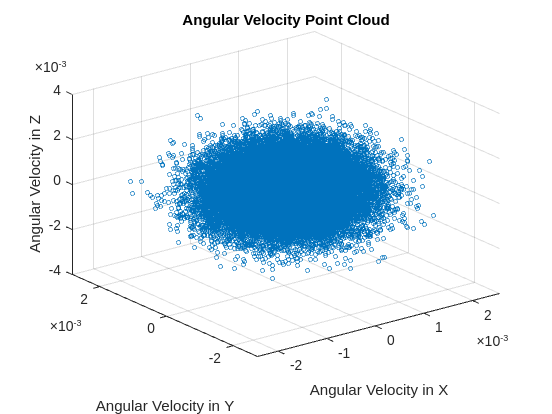


figure(11)
plot3(imu_gx, imu_gy, imu_gz, "o", "MarkerSize", 3);
title("Angular Velocity Point Cloud");
xlabel("Angular Velocity in X");
ylabel("Angular Velocity in Y");
zlabel("Angular Velocity in Z");
grid on

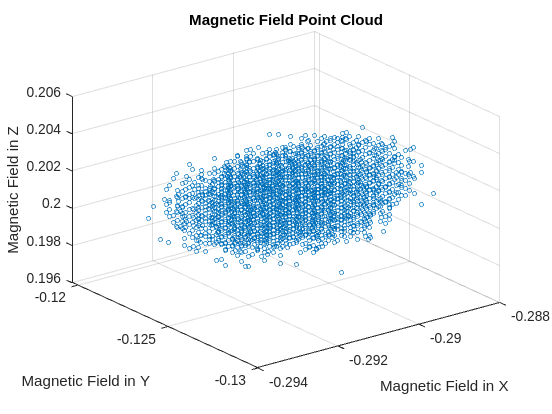


figure(12)
plot3(mag_x, mag_y, mag_z, "o", "MarkerSize", 3);
title("Magnetic Field Point Cloud");
xlabel("Magnetic Field in X");
ylabel("Magnetic Field in Y");
zlabel("Magnetic Field in Z");
grid on